# Compare spectrograms

Verify that images of spectrograms produced by

are visually similar to spectrograms produced by running Demo_Apply_CNN.ipynb.

Load the demo data and corresponding times

data = readmatrix('CNN_Spectrogram_Algorithm/Demo-Application/demo_data/data.csv');
time = readmatrix('CNN_Spectrogram_Algorithm/Demo-Application/demo_data/time.csv');
Fs = round(1/diff(time(1:2)));
winStep = round(Fs/2);

Get the spectrogram from the python implementation:

pythonSpectrogramLocation = ...
    ['CNN_Spectrogram_Algorithm/Demo-Application/' ...
    'demo_spectra_images/test/'];

Compute the spectrogram from the corresponding portion of the time series:

for k = 0:5
    im = imread(sprintf('%simg_%d.jpg' ...
    , pythonSpectrogramLocation, k));
    inds = k * winStep + (1:Fs);
    win = data(inds);
    [S, f, t] = compute_spectrogram(win, Fs);
    imMat = spectrogram2image(S);

Compare the resulting images:

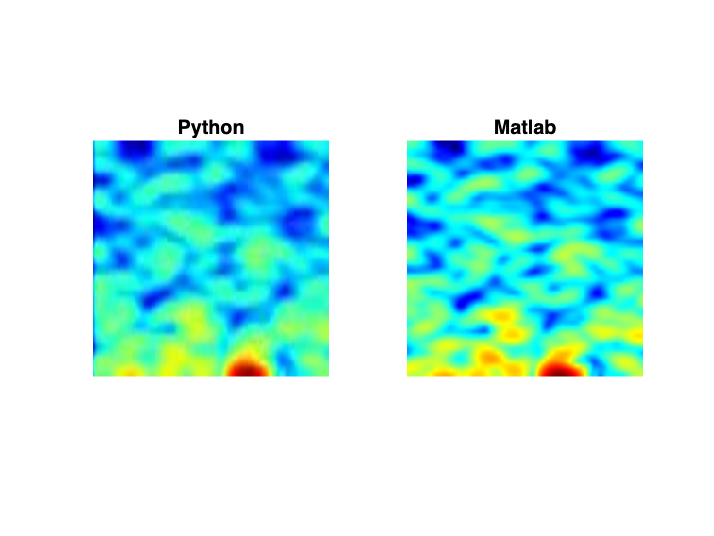

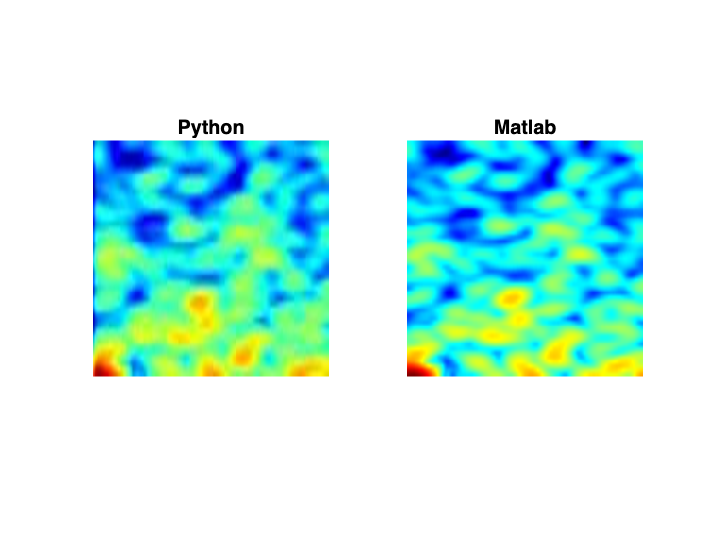

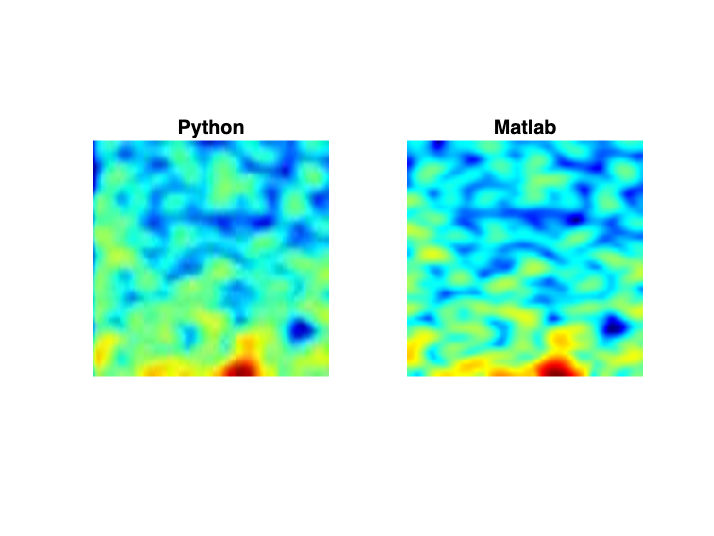

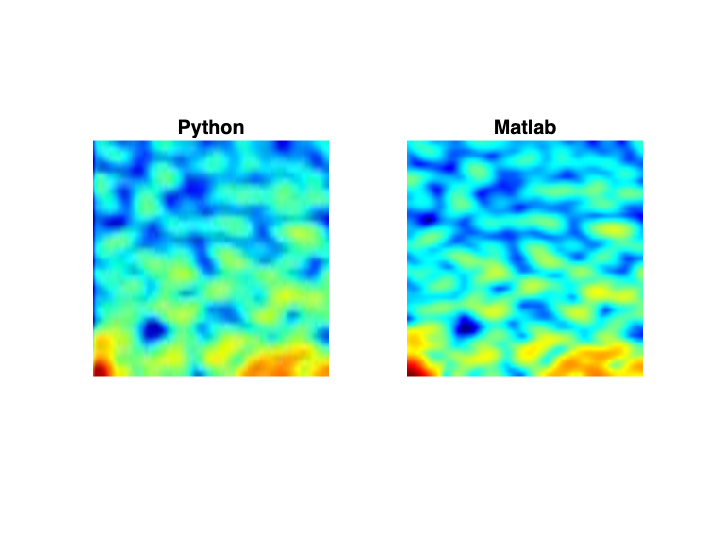

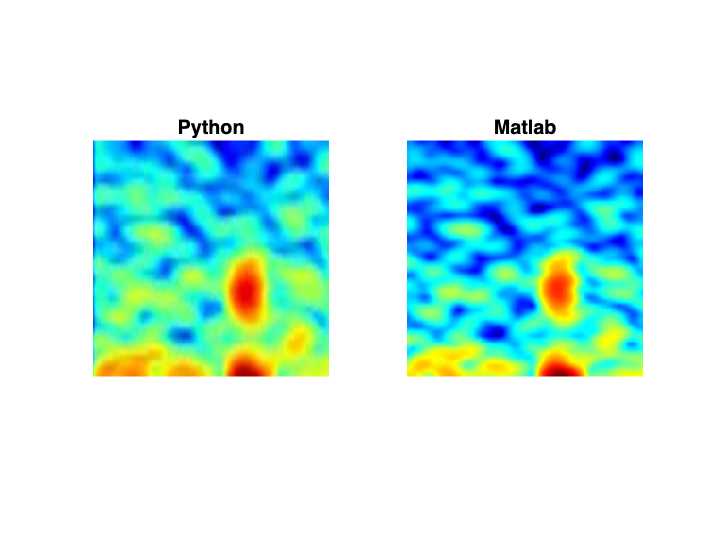

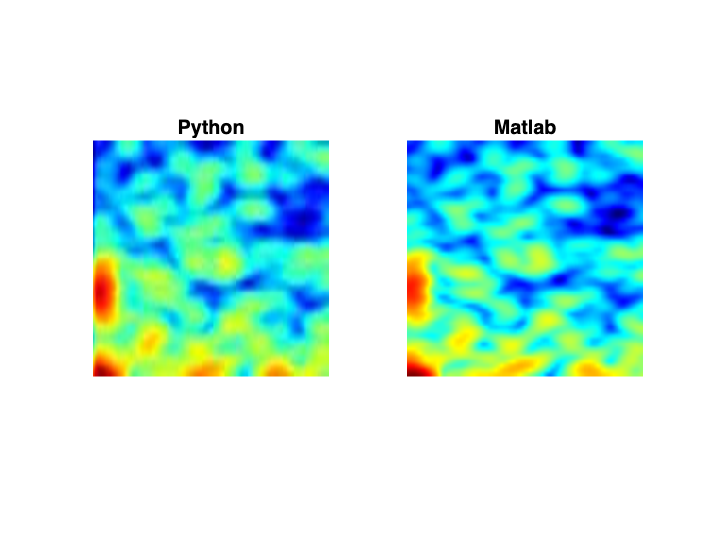

    resize_ = @(im) imresize(im, [250 250]);
    
    figure
    subplot(121)
%     imshow(resize_(rot90(permute(im, [2 1 3]), 2)))
    imshow(resize_(fliplr(rot90(im, 1))))
    title('Python')
    
    subplot(122)
    imshow(resize_(imMat))
    title('Matlab')

end

## Result

There is a little more smoothing in the python version, but they are pretty similar. 